# IMCL推定アルゴリズムの修正

検出点を信号最大値にしてしまうと，ノイズの影響を大きく受ける．そこで，相互相関をとり，時系列的にもっとも送信波形と似た形状の波形がある時刻を割出すことで検出の正確度を担保する．

対象：下の条件で得たデータ

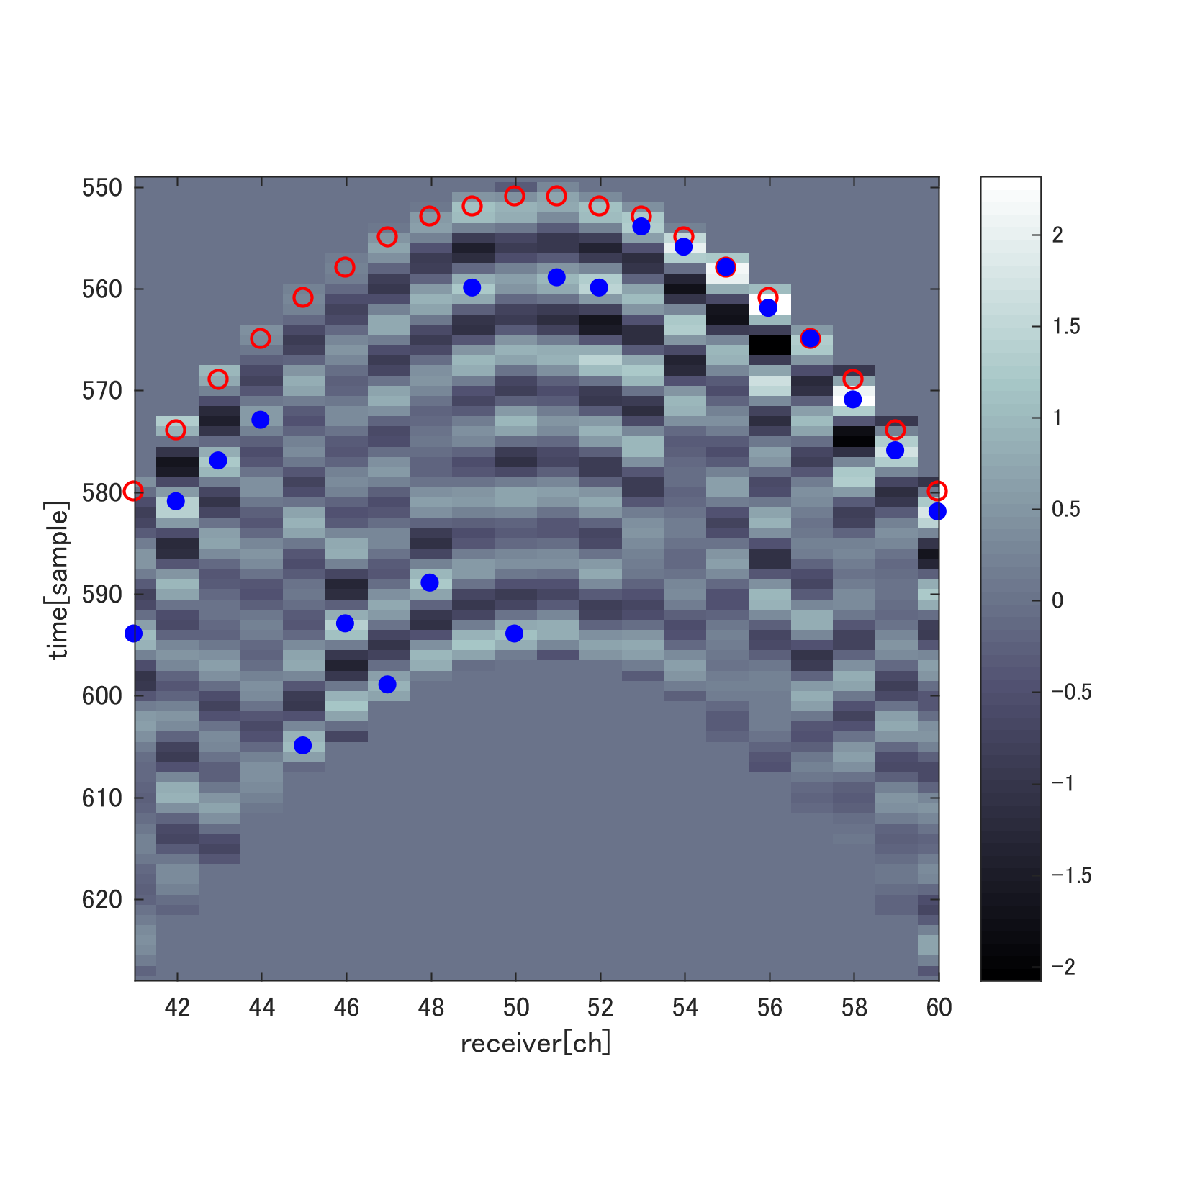

"H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_06_maxrfsignal_detect_boundary_case2

dst_path = 'H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_06_maxrfsignal_detect_boundary_case26\';
load([dst_path,'true2_assumption2\rfdata.mat']);
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL2.0_pure\sourse_wave.mat")
[acor,lag] = xcorr(abs(hilbert(focused_rfdata_masked(:,52))),abs(hilbert(source_wave)),'coeff');
reference_point(1,52);
[~,I] = max(abs(acor));
lagDiff = lag(I)

lagDiff = 534

結果をまとめたほうがいいのではないか．

あまり改善にはつながっていないことはたしか．

## 2018/11/19

焦点深度誤検出をなくした状態で議論する．

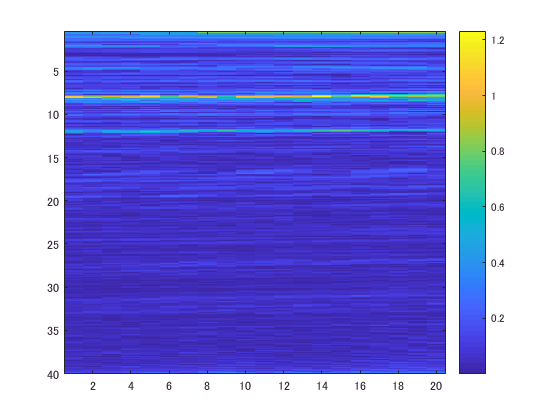

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_06_maxrfsignal_detect_boundary_case26\result2.mat")
imagesc(1:end,focal_depth*1e3,abs(hilbert(focal_signal_total(:,:,1))));
colorbar;

半値幅が設定音速と環境音速との違いで変わりそうか確認してみる．

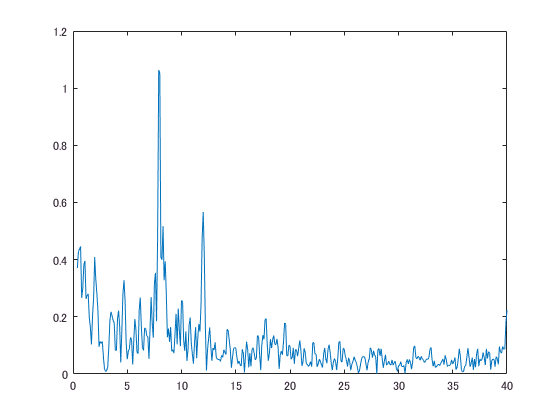

figure;
plot(focal_depth*1e3,abs(hilbert(focal_signal_total(:,1,1))));

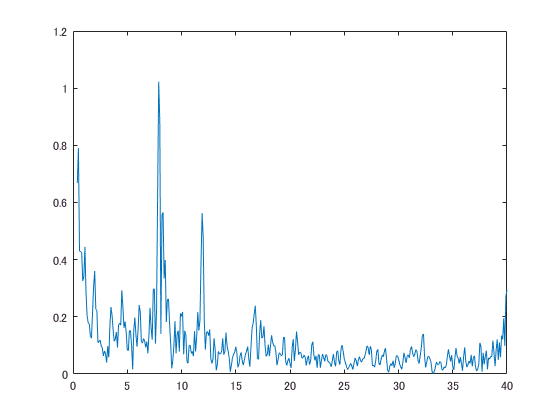

figure;
plot(focal_depth*1e3,abs(hilbert(focal_signal_total(:,10,1))));

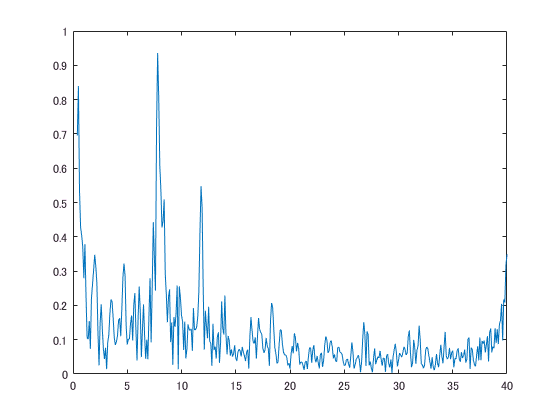

figure;
plot(focal_depth*1e3,abs(hilbert(focal_signal_total(:,20,1))));

半値幅が確かに設定音速と環境音速の違いが少ない場合において低減されたが，この要因として，設定音速の適切さが支配的なのか，あるいは設定音速と環境音速の誤差が媒質不均質さの補正としての役割を持つことによる効果が支配的なのかこのままでは弁別できない.

やはり境界位置を整相加算で見つけてそこから手前の領域の不均一さを評価．続いて不均一さがしきい値を下回っていたら信頼して，環境音速と設定音速との差を波面の曲率によって評価するのがよいとおもう．

マスク処理をかけないでRFデータを広く使ってやるのがよいと思った．

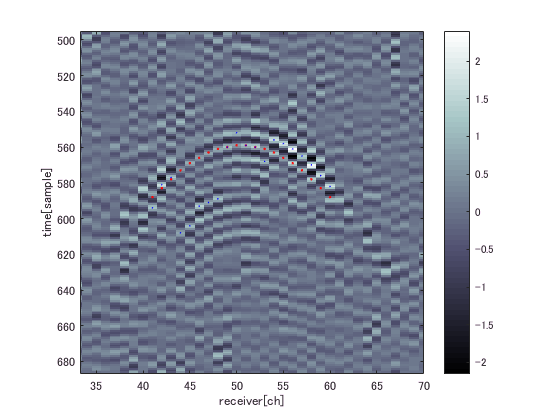

openfig('H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_06_maxrfsignal_detect_boundary_case26\true1_assumption20\rfdata_whole.fig');
xlim([33.3 70.0])
ylim([495 687])

隣合う素子での波形データの相互相関の最大値を評価することで，素子ごとの信号振幅最大値を評価するよりもノイズに強い変位追跡が可能になりそう．

ところで各設定音速での反射強度を正規化して積算した．境界深度がパッキリ見える様になった．

初期値を適当に決めて例えば5条件計測にして境界を見つけられるなら処理速度は上がりそう．

境界位置がわずかにシフトしているはずなのでそれも可視化したい．

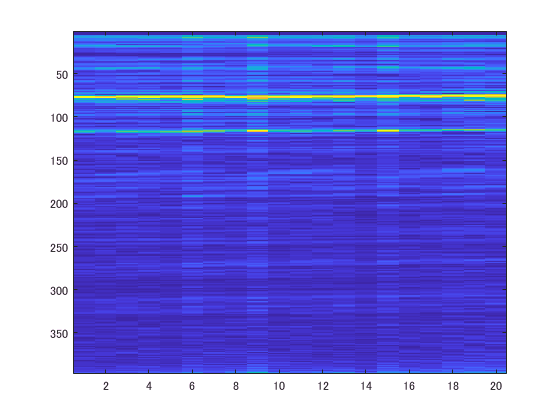

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_06_maxrfsignal_detect_boundary_case26\result2.mat")
a = abs(hilbert(focal_signal_total(:,:,1)));
a(1:5,:) = 0;
for ii = 1:20
    a(:,ii) = a(:,ii)/max(a(:,ii));
end
figure;
imagesc(a)

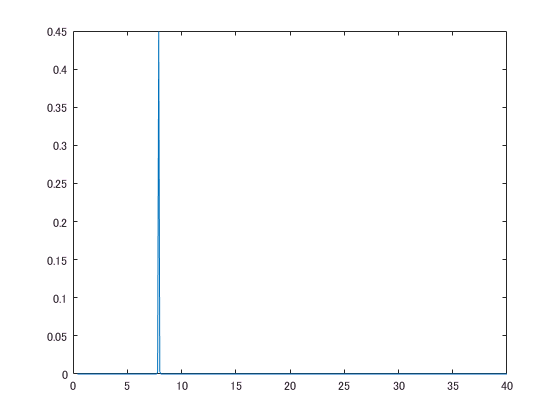

b = prod(a,2);
figure;plot(focal_depth*1e3,b)

## 2018/11/20

相互相関を用いた波面形状評価．プロトタイプをとりあえず作る．

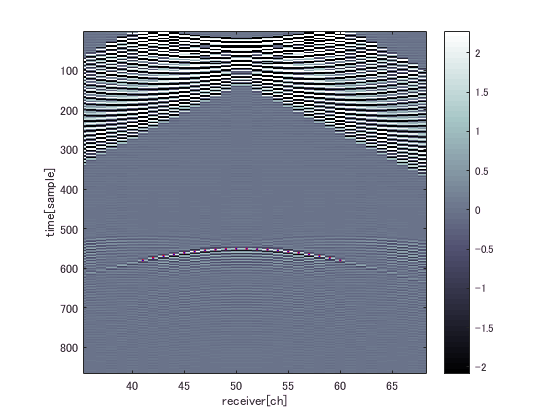

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_05_maxrfsignal_detect_boundary_2layers\true1_assumption1\rfdata.mat");
figure;
openfig('H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_05_maxrfsignal_detect_boundary_2layers\true1_assumption1\rfdata_whole.fig');
xlim([35.3 68.3])
ylim([1 867])

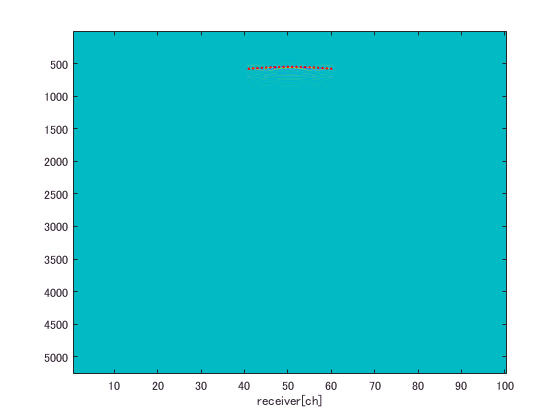

min_reference = min(reference_point) - 100;
max_reference = min(reference_point) + 500 - 1;
mask_rfdata = zeros(size(focused_rfdata));
mask_rfdata(min_reference:max_reference,41:60) = 1;
masked_rfdata = mask_rfdata .* focused_rfdata;
figure;
imagesc(masked_rfdata);
hold on
scatter(41:60,reference_point(41:60),2,'red');
xlabel('receiver[ch]');load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_05_maxrfsignal_detect_boundary_2layers\true1_assumption1\rfdata.mat");

figure;
openfig('H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_05_maxrfsignal_detect_boundary_2layers\true1_assumption1\rfdata_whole.fig');
xlim([35.3 68.3])
ylim([1 867])

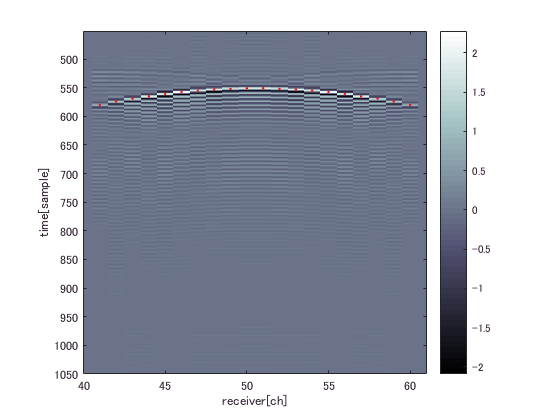

min_reference = min(reference_point) - 100;
max_reference = min(reference_point) + 500 - 1;
mask_rfdata = zeros(size(focused_rfdata));
mask_rfdata(min_reference:max_reference,41:60) = 1;
masked_rfdata = mask_rfdata .* focused_rfdata;
figure;
imagesc(masked_rfdata);
hold on
scatter(41:60,reference_point(41:60),2,'red');
xlabel('receiver[ch]');
ylabel('time[sample]');
axis square;
axis tight;
xlim([40 61])
ylim([min_reference max_reference])
colormap(bone);
colorbar;
caxis([min(min(masked_rfdata)) max(max(masked_rfdata))])

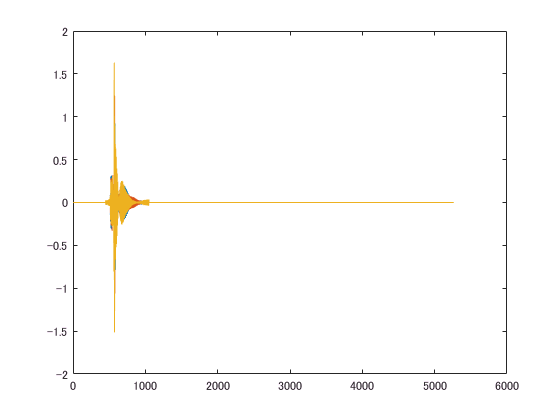

figure;
plot(masked_rfdata(:,41));
hold on
plot(masked_rfdata(:,42));
plot(masked_rfdata(:,43));

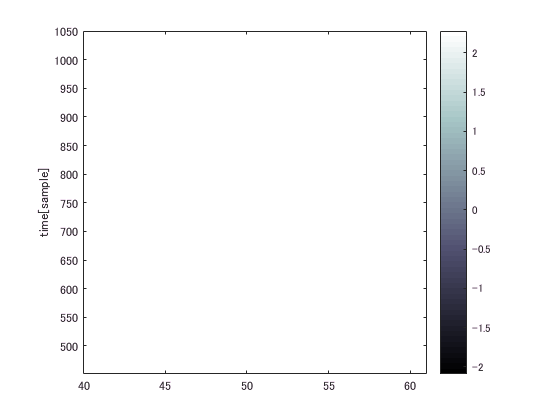

displacement = zeros(20,1);
curvature = zeros(20,1);
for ii = 41:60-1
    [acor,lag] = xcorr(masked_rfdata(:,ii+1),masked_rfdata(:,ii),'coeff');
    [~,I] = max(abs(acor));
    displacement(ii-40+1) = lag(I);
end
for ii = 1:20
    curvature(ii) = sum(displacement(1:ii));
end
figure;
plot(curvature);
hold on
plot(reference_point(41:60)-max(reference_point(41:60)),'.');
ylabel('time[sample]');
axis square;
axis tight;
xlim([40 61])
ylim([min_reference max_reference])
colormap(bone);
colorbar;
caxis([min(min(masked_rfdata)) max(max(masked_rfdata))])

figure;
plot(masked_rfdata(:,41));
hold on
plot(masked_rfdata(:,42));
plot(masked_rfdata(:,43));

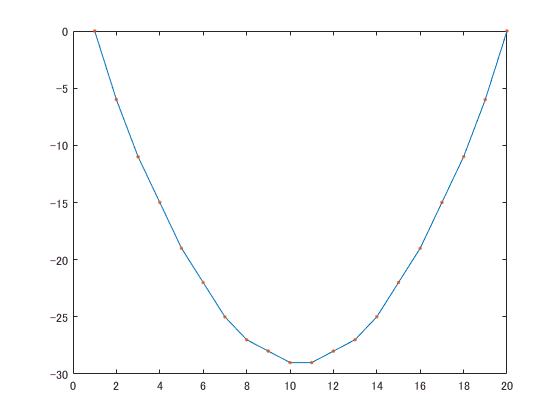

displacement = zeros(20,1);
curvature = zeros(20,1);
for ii = 41:60-1
    [acor,lag] = xcorr(masked_rfdata(:,ii+1),masked_rfdata(:,ii),'coeff');
    [~,I] = max(abs(acor));
    displacement(ii-40+1) = lag(I);
end
for ii = 1:20
    curvature(ii) = sum(displacement(1:ii));
end
figure;
plot(curvature);
hold on
plot(reference_point(41:60)-max(reference_point(41:60)),'.');

非常に当てはまりがよい．

つづいて複雑媒質でのRFデータに適用する．

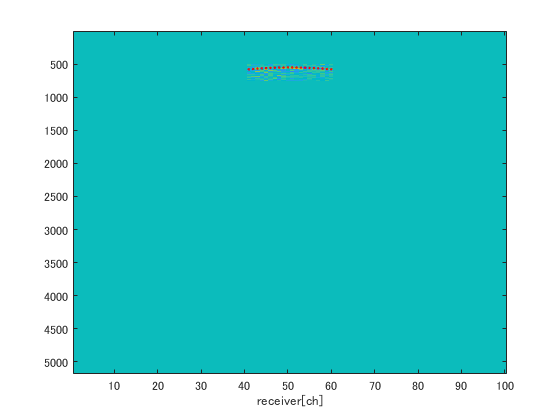

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_06_maxrfsignal_detect_boundary_case26\true20_assumption20\rfdata.mat");
figure;
openfig('H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_06_maxrfsignal_detect_boundary_case26\true20_assumption20\rfdata_masked.fig');
xlim([35.3 68.3])
ylim([1 867])
min_reference = min(reference_point) - 50;
max_reference = min(reference_point) + 200 - 1;
mask_rfdata = zeros(size(focused_rfdata));
mask_rfdata(min_reference:max_reference,41:60) = 1;
masked_rfdata = mask_rfdata .* focused_rfdata;
figure;
imagesc(masked_rfdata);
hold on
scatter(41:60,reference_point(41:60),2,'red');
xlabel('receiver[ch]');

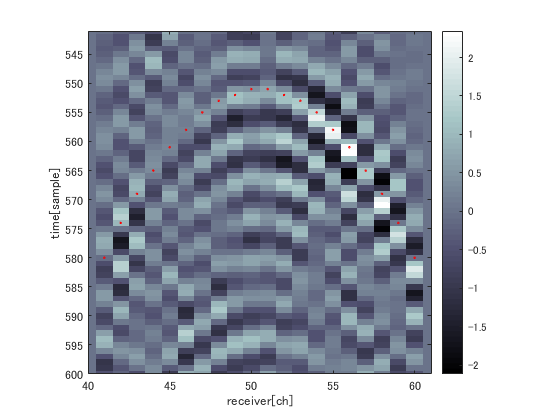

load("H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_06_maxrfsignal_detect_boundary_case26\true1_assumption1\rfdata.mat");
figure;
openfig('H:\result\2018_11_07_IMCL_estimation_principle_verifiacation\2018_11_11_no_06_maxrfsignal_detect_boundary_case26\true1_assumption1\rfdata_whole.fig');
xlim([35.3 68.3])
ylim([1 867])
min_reference = min(reference_point) - 5;
max_reference = min(reference_point) + 40 - 1;
mask_rfdata = zeros(size(focused_rfdata));
mask_rfdata(min_reference:max_reference,41:60) = 1;
masked_rfdata = mask_rfdata .* focused_rfdata;
min_reference = min(reference_point) - 10;
max_reference = min(reference_point) + 50 - 1;
mask_rfdata_ref = zeros(size(focused_rfdata));
mask_rfdata_ref(min_reference:max_reference,41:60) = 1;
masked_rfdata_ref = mask_rfdata_ref .* focused_rfdata;
figure;
imagesc(masked_rfdata_ref);
hold on
scatter(41:60,reference_point(41:60),2,'red');
xlabel('receiver[ch]');
ylabel('time[sample]');
axis square;
axis tight;
xlim([40 61])
ylim([min_reference max_reference])
colormap(bone);
colorbar;
caxis([min(min(masked_rfdata)) max(max(masked_rfdata))])

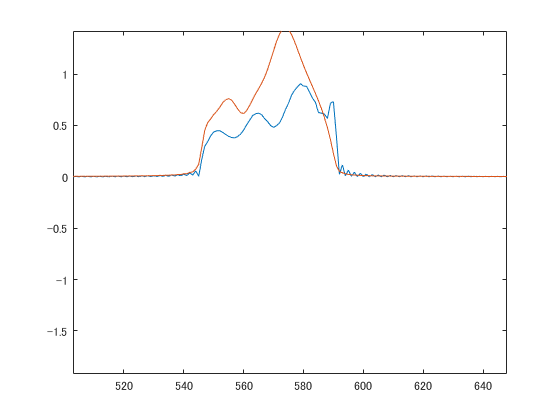

figure;
plot(abs(hilbert(masked_rfdata(:,41))));
hold on
% plot(abs(hilbert(masked_rfdata(:,42))));
plot(abs(hilbert(masked_rfdata(:,43))));
hold off
xlim([503 648])
ylim([-1.92 1.42])

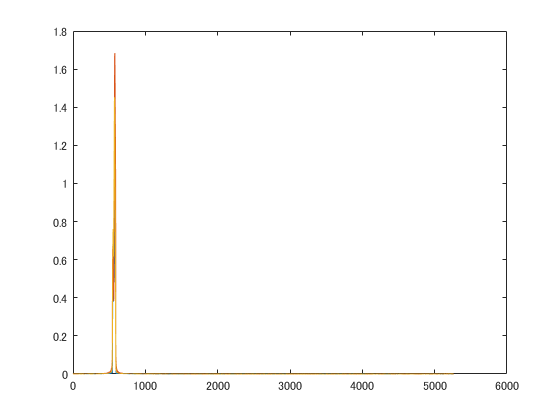

displacement = zeros(20,1);
curvature = zeros(20,1);
max_delay = [8 7 6 6 5 5 5 4 3 2 3 4 5 5 5 6 6 7 8];
for ii = 41:60-1
    displacement(ii-40+1) = - finddelay(masked_rfdata_ref(:,ii+1),masked_rfdata(:,ii),max_delay(ii-40));
end

figure;
plot(abs(hilbert(masked_rfdata(:,41))));
hold on
plot(abs(hilbert(masked_rfdata(:,42))));
plot(abs(hilbert(masked_rfdata(:,43))));

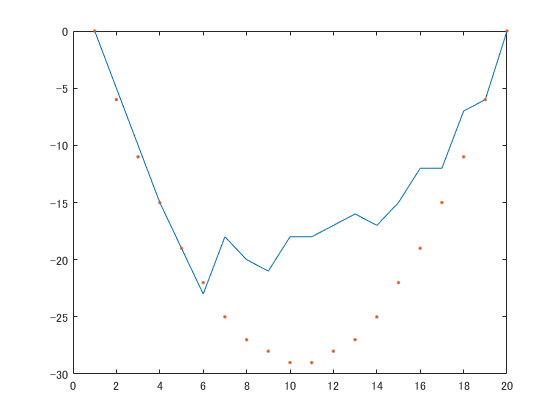


for ii = 1:20
    curvature(ii) = sum(displacement(1:ii));
end
figure;
plot(curvature);
hold on
plot(reference_point(41:60)-max(reference_point(41:60)),'.');

二次関数にフィッティングして参照点列と検出点列との整合性をみる

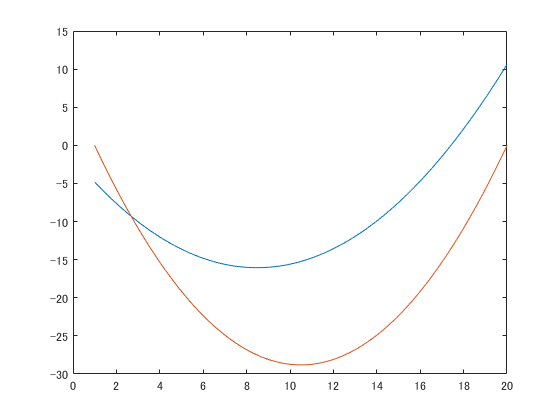

p2 = polyfit(1:1:20,reference_point(41:60)-max(reference_point(41:60)),2);
p1 = polyfit(1:1:20,curvature',2);
x1 = 1:0.01:20;
y1 = polyval(p1,x1);
x2 = x1;
y2 = polyval(p2,x2);
figure;
plot(x1,y1);
hold on
plot(x2,y2);

送信波形のパワースペクトル

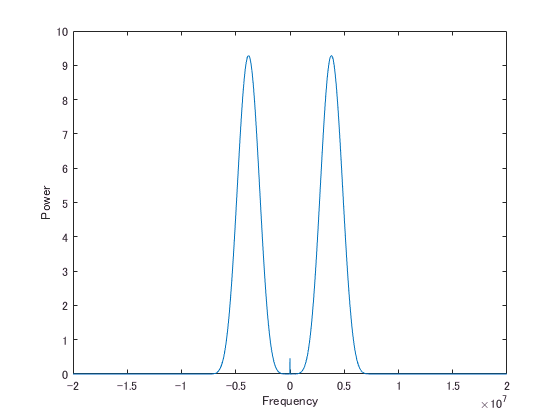

load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL20.0_pure\param.mat")
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL20.0_pure\kgrid.mat")
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL20.0_pure\sourse_wave.mat")

fs = param.sensor.freq;
t = kgrid.t_array;
y = fft(source_wave);
n = length(t);


y0 = fftshift(y);         % shift y values
f0 = (-n/2:n/2-1)*(fs/n); % 0-centered frequency range
power0 = abs(y0).^2/n;    % 0-centered power

figure;
plot(f0,power0)
xlabel('Frequency')
ylabel('Power')

受信信号のパワースペクトル

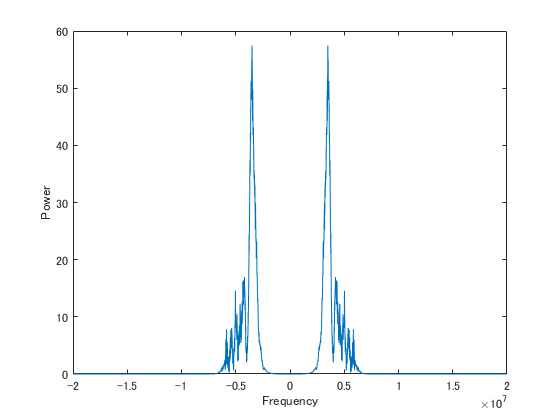

load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL20.0_pure\param.mat")
load("H:\data\kwave\result\2018_11_11_case26_variousIMCL\case26_IMCL20.0_pure\kgrid.mat")
fs = param.sensor.freq;
t = kgrid.t_array;
y = fft(focused_rfdata(:,51));
n = length(t);


y0 = fftshift(y);         % shift y values
f0 = (-n/2:n/2-1)*(fs/n); % 0-centered frequency range
power0 = abs(y0).^2/n;    % 0-centered power

figure;
plot(f0,power0)
xlabel('Frequency')
ylabel('Power')

## 2018/11/21

位相限定相関をとる．

ロバストらしい．

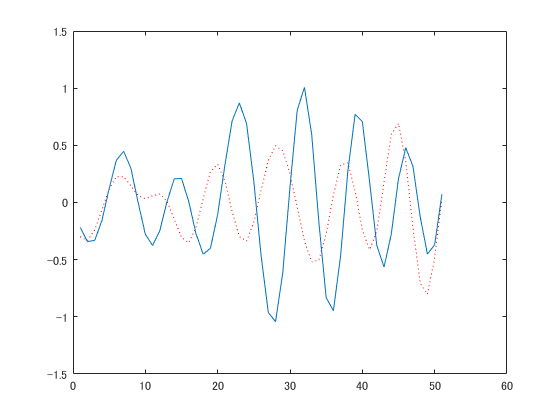

load("H:\result\2018_11_16_IMCL_estimation_principle_correct\2018_11_21_savepoint.mat");
% mask_rfdata_41 = masked_rfdata_ref(:,41);
% mask_rfdata_42 = masked_rfdata(:,42);
a = focused_rfdata(550:600,41);
b =focused_rfdata(550:600,42);
mask_rfdata_base = a;
mask_rfdata_object = b;
figure;
plot(mask_rfdata_base,':r');
hold on
plot(mask_rfdata_object);
hold off

フーリエ変換する

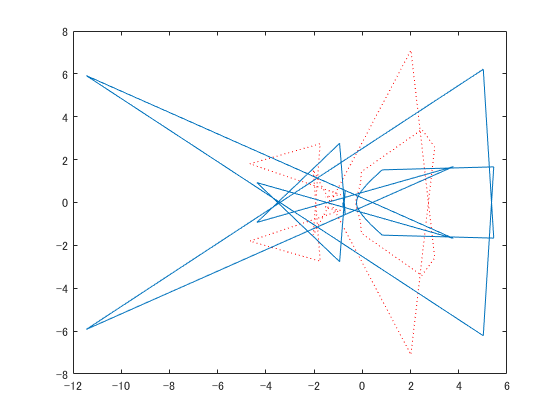

fft_rfdata_41 = fft(mask_rfdata_base);
fft_rfdata_42 = fft(mask_rfdata_object);
figure;
plot(fft_rfdata_41,':r');
hold on
plot(fft_rfdata_42);

fft_rfdata_42の複素共役をとる．

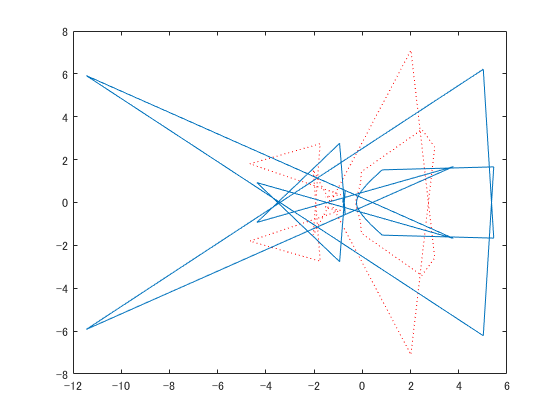

conj_fft_rfdata_42 = conj(fft_rfdata_42);
figure;
plot(fft_rfdata_41,':r');
hold on
plot(conj_fft_rfdata_42);
hold off

共役をとったときの違いがあまりわからないのでfft_rfdata_42とfft_rfdata_42の複素共役とで比較する．

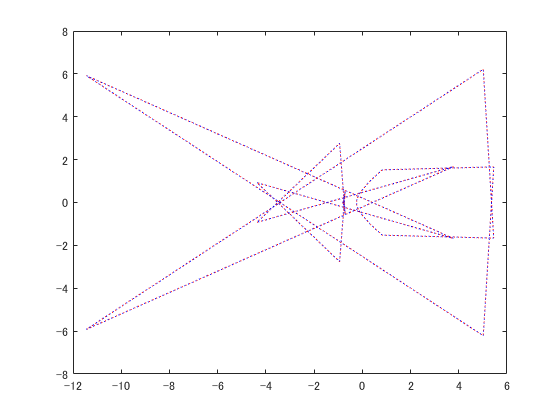

conj_fft_rfdata_42 = conj(fft_rfdata_42);
figure;
plot(fft_rfdata_42,':r');
hold on
plot(conj_fft_rfdata_42,':b');
hold off

FFTR: F(ROC)を求める．POCを求める

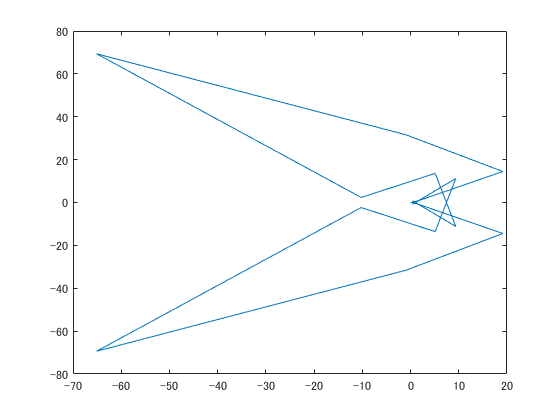

FFTR = fft_rfdata_41 .* conj_fft_rfdata_42;
figure;
plot(FFTR);

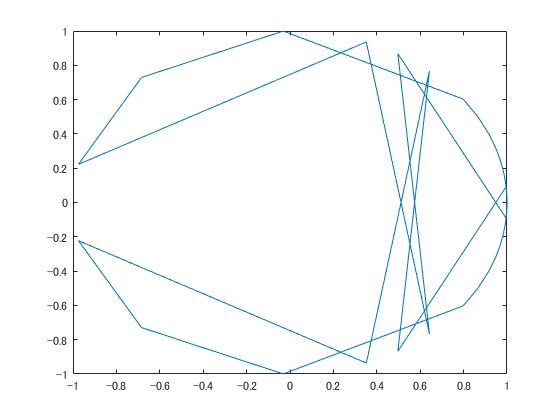

FFTRN = FFTR./abs(FFTR);
figure;
plot(FFTRN);

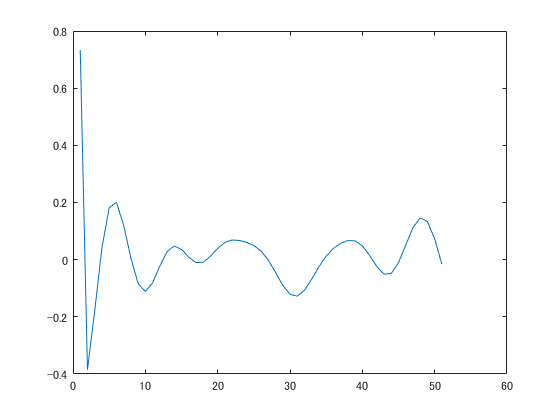

CROC=real(ifft(FFTRN));
figure;
plot(CROC);

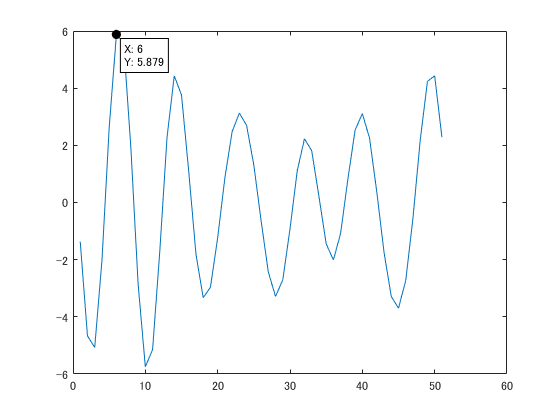

a = ifft(FFTR);
figure;
plot(a);

他の組み合わせでも精度よく時間シフトがわかるか検討する．

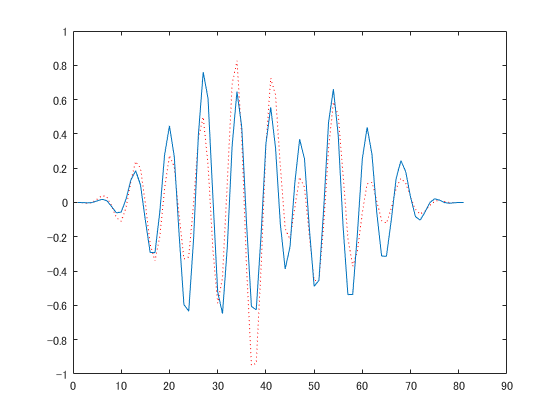

load("H:\result\2018_11_16_IMCL_estimation_principle_correct\2018_11_21_savepoint.mat");
% mask_rfdata_41 = masked_rfdata_ref(:,41);
% mask_rfdata_42 = masked_rfdata(:,42);
a = focused_rfdata(540:620,50);
b = focused_rfdata(540:620,51);
han_width = length(a);
han_window = hann(han_width);
a = a.*han_window;
b = b.*han_window; 
mask_rfdata_base = a;
mask_rfdata_object = b;
figure;
plot(mask_rfdata_base,':r');
hold on
plot(mask_rfdata_object);
hold off

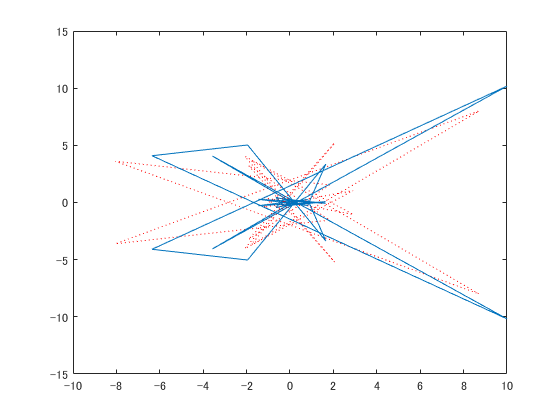

fft_rfdata_41 = fft(mask_rfdata_base);
fft_rfdata_42 = fft(mask_rfdata_object);
figure;
plot(fft_rfdata_41,':r');
hold on
plot(fft_rfdata_42);

fft_rfdata_41 = fft(mask_rfdata_base);
fft_rfdata_42 = fft(mask_rfdata_object);
figure;
plot(fft_rfdata_41,':r');
hold on
plot(fft_rfdata_42);

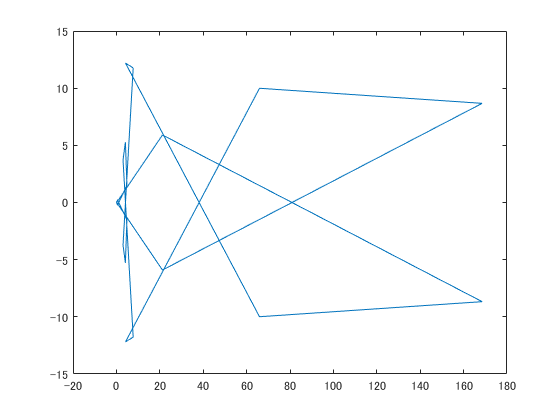

conj_fft_rfdata_42 = conj(fft_rfdata_42);
FFTR = fft_rfdata_41 .* conj_fft_rfdata_42;
figure;
plot(FFTR);

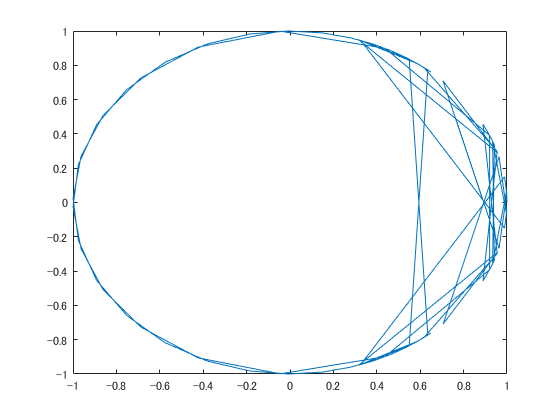

FFTRN = FFTR./abs(FFTR);
figure;
plot(FFTRN);

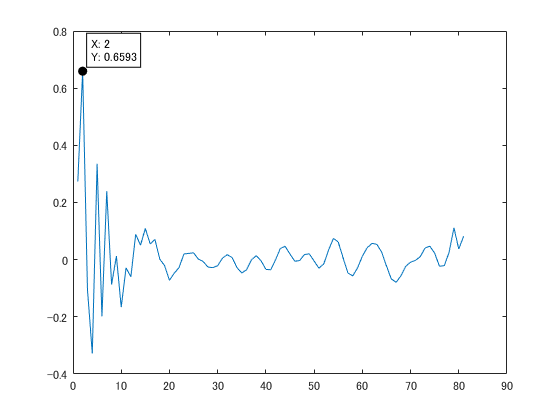

CROC=real(ifft(FFTRN));
figure;
plot(CROC);

クロススペクトルを求める．その逆フーリエ変換である相互相関と直接的な相互相関を比較する．

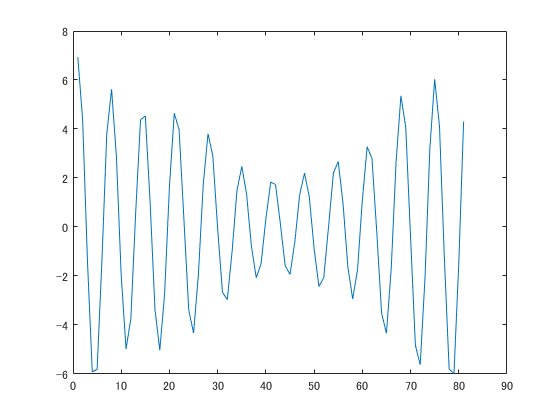

crossAB = fft(mask_rfdata_object) .* conj(fft(mask_rfdata_base));
powerA = fft(mask_rfdata_base) .* conj(fft(mask_rfdata_base));
powerB = fft(mask_rfdata_object) .* conj(fft(mask_rfdata_object));
r_crossA = ifft(crossAB);
figure;
plot(r_crossA);

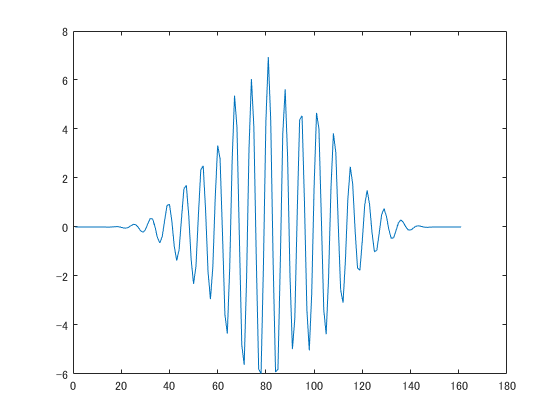


figure;
plot(r_corrA);

クロススペクトルの位相傾きを求める．

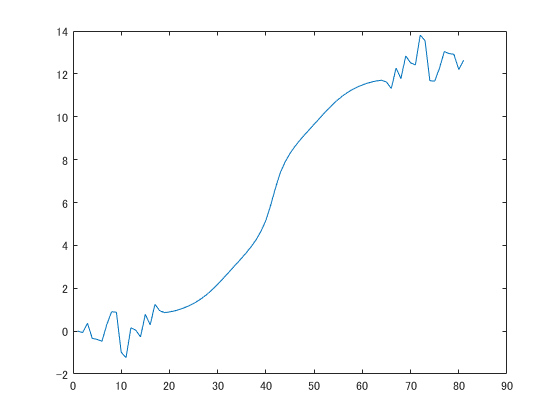

figure;
plot(unwrap(angle(crossAB)));

Rothによる方法を試す

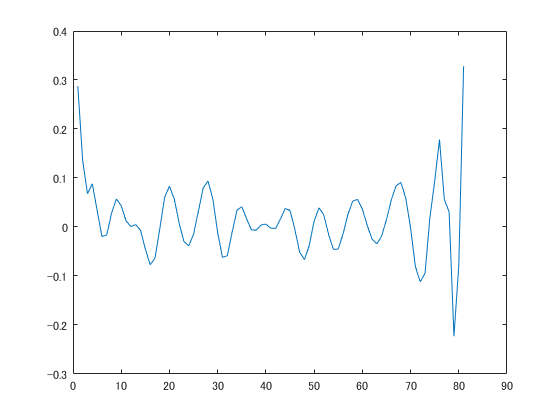

figure;
r_roth = ifft(crossAB./powerA);
figure;
plot(r_roth);

figure;
plot(unwrap(angle(crossAB./powerA)));

scottによる方法を試す

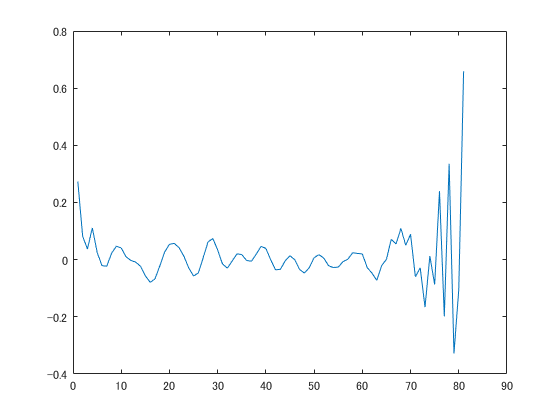

figure;
r_scott = ifft(crossAB./sqrt(powerA.*powerB));
figure;
plot(r_scott);

figure;
plot(unwrap(angle(crossAB./(powerA.*powerB))));

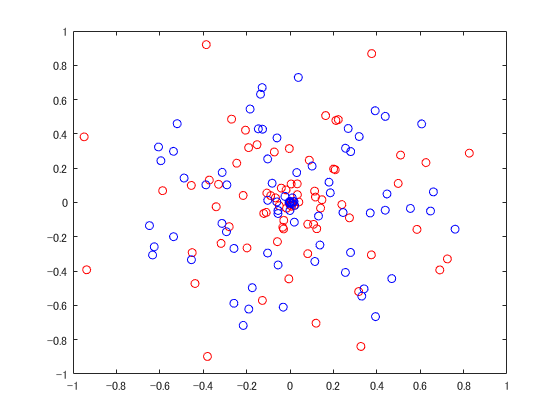

hilbertA = hilbert(mask_rfdata_base);
hilbertB = hilbert(mask_rfdata_object);
figure;
plot(hilbertA,'ro');
hold on
plot(hilbertB,'bo');

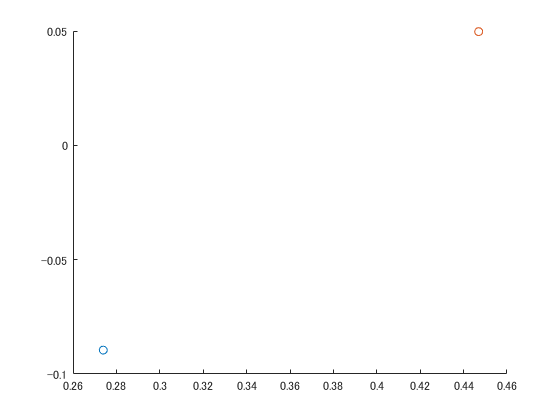

figure;
scatter(real(hilbertA(20)),imag(hilbertA(20)));
hold on
scatter(real(hilbertB(20)),imag(hilbertB(20)));

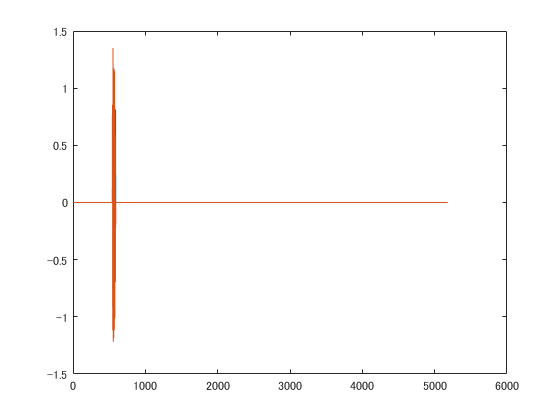

figure;
plot(focused_rfdata_masked(:,48));
hold on
plot(focused_rfdata_masked(:,53));
hold off

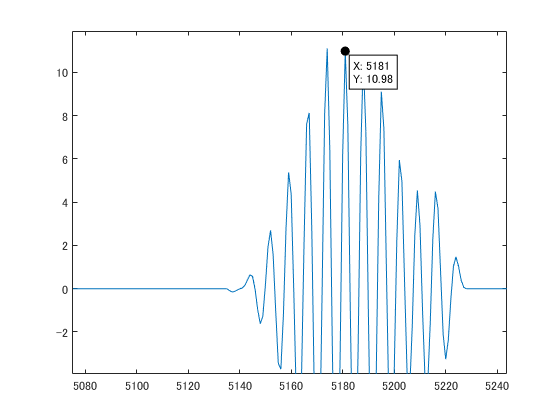

figure;
plot(xcorr(focused_rfdata_masked(:,48),focused_rfdata_masked(:,53)));